# Lab 1 Notebook

## 1. Normal Distributions, Integrals, and Probabilities

### A. The Normal Distribution

A normal distribution a set of data points which is centered around the mean value. It is symmetric, with mean (mu) = median = mode, and is often called a "Gaussian distribution" or a "bell curve" due to its shape, as seen to the right.

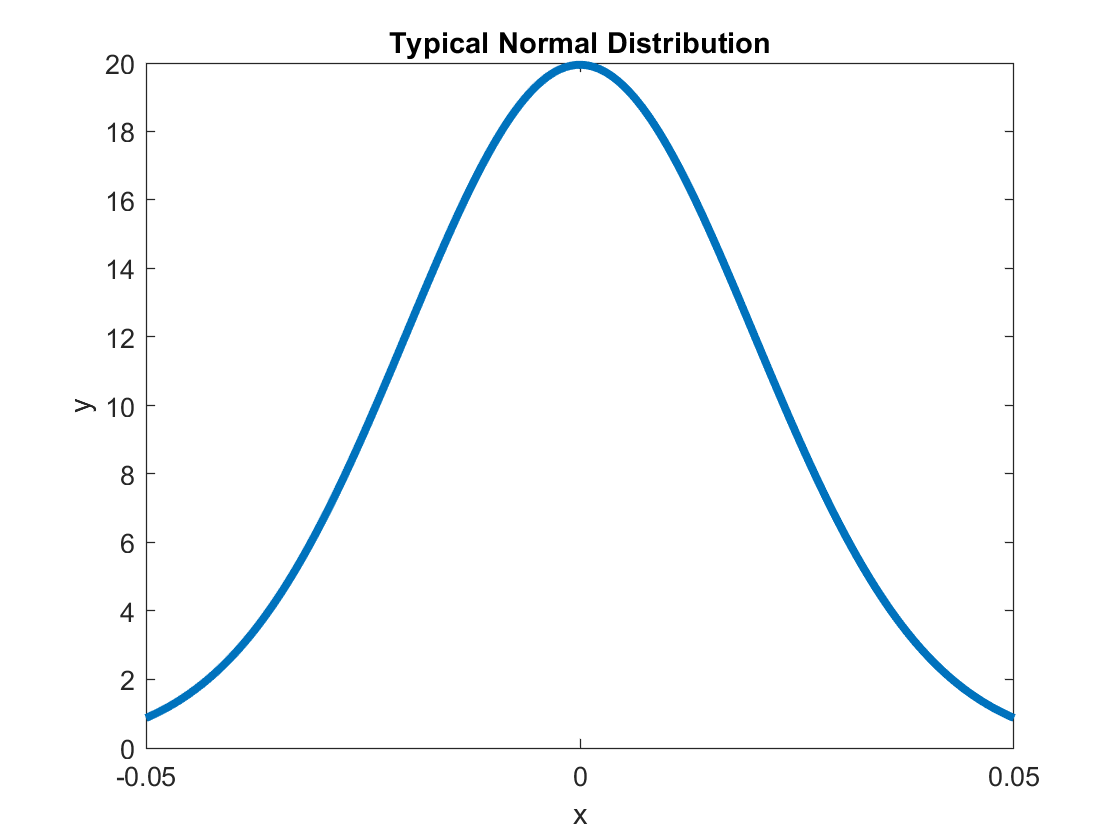

x = linspace(-0.05,0.05,1000);
bellcurve = makedist("Normal","mu",0.,"sigma",0.02);
plot(x,pdf(bellcurve,x),"LineWidth",3)

title('Typical Normal Distribution')
xlabel('x')
ylabel('y')

One numerical value associated with a normal distribution is the standard deviation, represented by a sigma. Standard deviation is a measure of the spread of the data, for instance a smaller standard deviation results in a thinner, higher peak whereas a larger standard deviation indicates a wider, more spread out set of data points. 

Generally, 68% of values are within one standard deviation of the mean, 95% of values are within two standard deviations, and 99.7% of values are within three standard deviations. 

#### The Standard Normal Distribution

In a standard normal distribution, which is a particular subset of normal distributions, the mean is 0 and the standard deviation is 1. 

#### Mathematical Representation

Typical probability density function: 

f(x) = 1/(sigma*sqrt(2*pi))*exp(-0.5*((x-mu)/sigma)^2)

Standard normal probablility density function:

p(x) = 1/sqrt(2*pi)*exp(-0.5*x^2)

Note that the factor 1/(sigma*sqrt(2*pi)) lets the integral from negative infinity to positive infinity be 1, effectively normalizing the data and allowing the function to give a probability. Taking the integral of f on the interval [a,b] gives the probability of a data point being in that section of the distribution. 

### B. Integrating the Standard Normal Distribution

Below are examples of finding probabilities by integrating normal distributions of various sigmas.

- Standard normal: mu = 0, sigma = 1

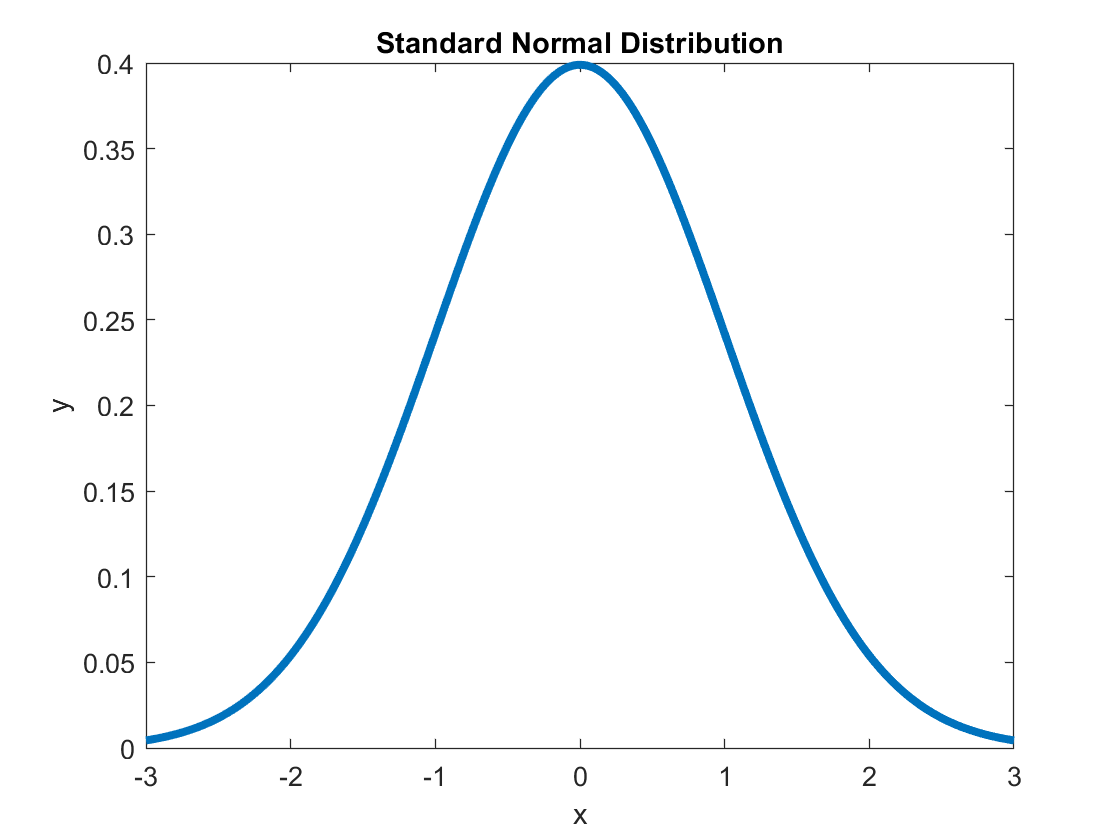

x2 = linspace(-3,3,1000);
bellcurve2 = makedist("Normal","mu",0.,"sigma",1);
plot(x2,pdf(bellcurve2,x2),"LineWidth",3)

title('Standard Normal Distribution')
xlabel('x')
ylabel('y')


p_a = normcdf(-1.5)

p_a = 0.0668


p_b = normcdf(1.5)

p_b = 0.9332


c = [-1,1];
prob_c = normcdf(c);
p_c = prob_c(2)-prob_c(1)

p_c = 0.6827

           2. mu = 0, sigma = 0.5

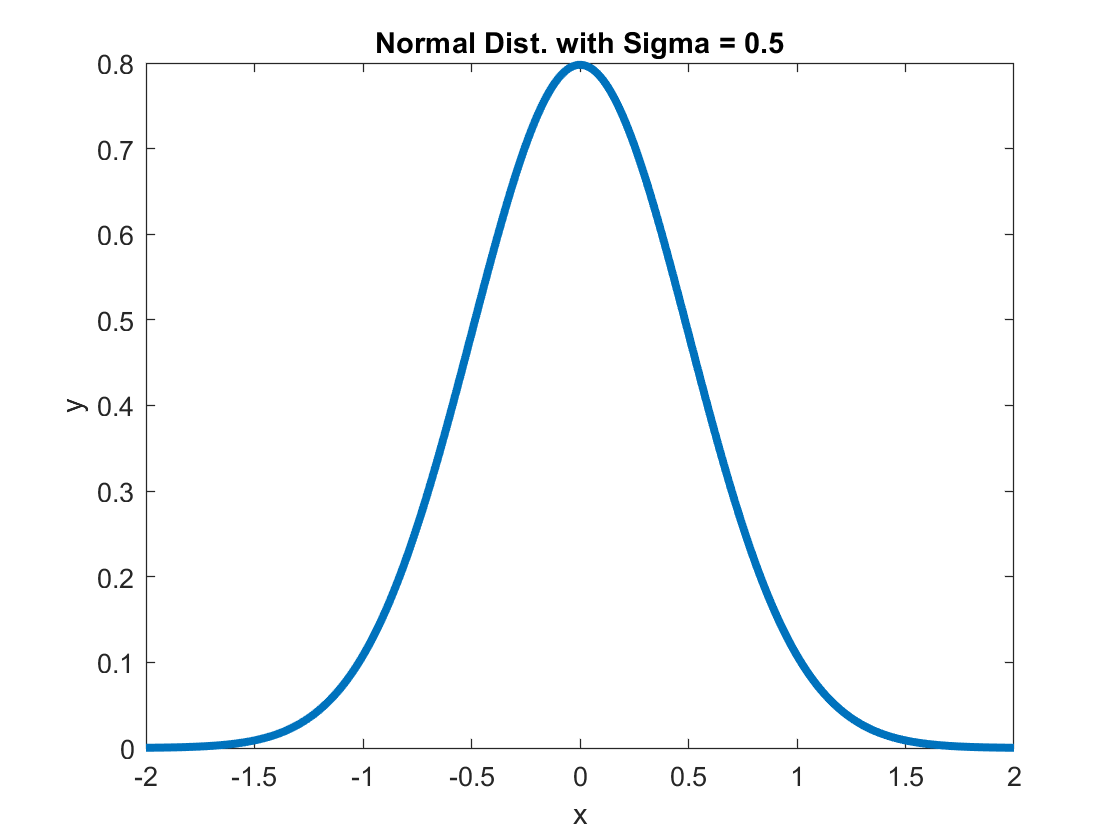

x3 = linspace(-2,2,1000);
bellcurve3 = makedist("Normal","mu",0.,"sigma",0.5);
plot(x3,pdf(bellcurve3,x3),"LineWidth",3)

title('Normal Dist. with Sigma = 0.5')
xlabel('x')
ylabel('y')


p_d = normcdf(-1.5,0,0.5)

p_d = 0.0013


p_e = normcdf(1.5,0,0.5)

p_e = 0.9987


p_f = normcdf(1,0,0.5) - normcdf(-1,0,0.5)

p_f = 0.9545

            3. mu = 0, sigma = 2

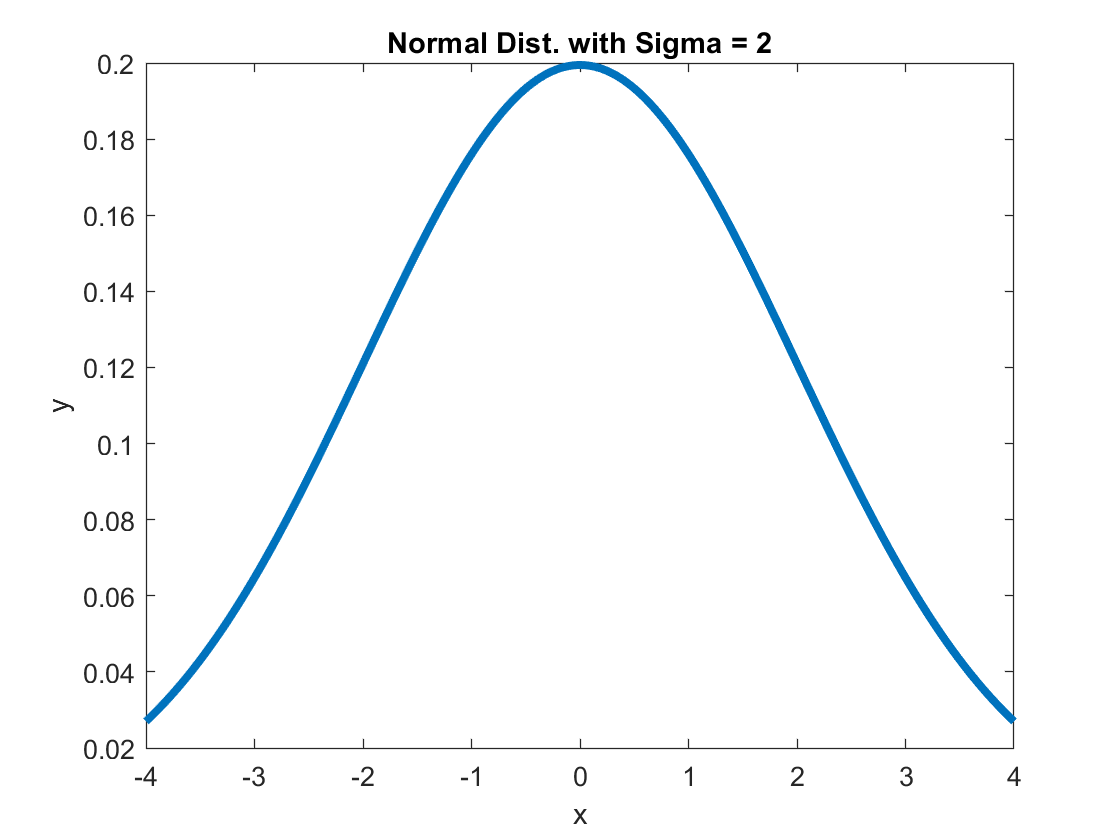

x4 = linspace(-4,4,1000);
bellcurve4 = makedist("Normal","mu",0.,"sigma",2);
plot(x4,pdf(bellcurve4,x4),"LineWidth",3)

title('Normal Dist. with Sigma = 2')
xlabel('x')
ylabel('y')


p_g = normcdf(-1.5,0,2)

p_g = 0.2266


p_h = normcdf(1.5,0,2)

p_h = 0.7734


p_i = normcdf(1,0,2) - normcdf(-1,0,2)

p_i = 0.3829

The various graphs show how sigma affects the spread of the graph, and the probabilities listed below give values for the intervals

- (-infinity, -1.5)

- (-infinity, 1.5)

- (-1,1)

for all three sigmas. 

<z table values>

### C. 'Sigmas'

In physics, 'sigma' can also refer to a probability. For any distribution, the probability of the background giving a data point that looks as or more signal-like than the actual reading is equal to the probability as if the data was Gaussian and the point in question was X*sigma away from the mean. In this context, sigma is shorthand for probability. 

Below are several examples of finding the sigma for various probabilities. In these example, I use norminv(p), which uses a standard normal distribution (sigma = 1, mu = 0). 

The expected values are: 

p_1 = 2.7*10^-7; 5 sigma

p_2 = 0.003; 3 sigma

p_1 = 2.7*10^(-7);
xsigma_1 = norminv(p_1)

xsigma_1 = -5.0115


p_2 = 0.003;
xsigma_2 = norminv(p_2)

xsigma_2 = -2.7478

Clearly, the sigma values are more accurate with a smaller input probability, but for both p_1 and p_2, norminv returned a value close to the predicted sigma value. 

### D. Negative 'Sigma' 

As you can see in my example above, the probabilities I used returned a negative sigma value. I believe this is a consequence of the way norminv calculates the sigma value; it likely integrates from right to left, so small probabilities (<50%) like the ones in my example would be on the "negative" side of the distribution, resulting in a negative sigma. The negative is less important than the absolute value, which tells you how far away from the mean the data point would appear on a Gaussian distribution. For instance, I could take p_3 = 1 - p_2 and determine its sigma value:

p_3 = 1-p_1;
xsigma_3 = norminv(p_3)

xsigma_3 = 5.0115

The absolute value of the sigma value is the same for p_1 and p_3, so they are equally far away from the mean. The negative indicates only which side of the distribution the data point is placed. 

## 2. Other Continuous Analytic Distributions

d = raylrnd(0.5,1,100000);

### A. Rayleigh Distribution

The Rayleigh distribution is characterized by the probability density function f(x, sigma) = x/sigma^2*exp(-(x^2)/(2*sigma^2)) where x > 0 or x = 0. Sigma in this context is the scale parameter, which is directly proportional to the spread of the distribution. 

The mean of the Rayleigh distribution mu = sigma*sqrt(pi/2). 

### B. Plotting a Rayleigh Distrubution

The graph of a Rayleigh distribution is characterized by a tall, skewed peak with a tail, as shown below. The sharpness of the peak and tail are determined by the value of sigma. 

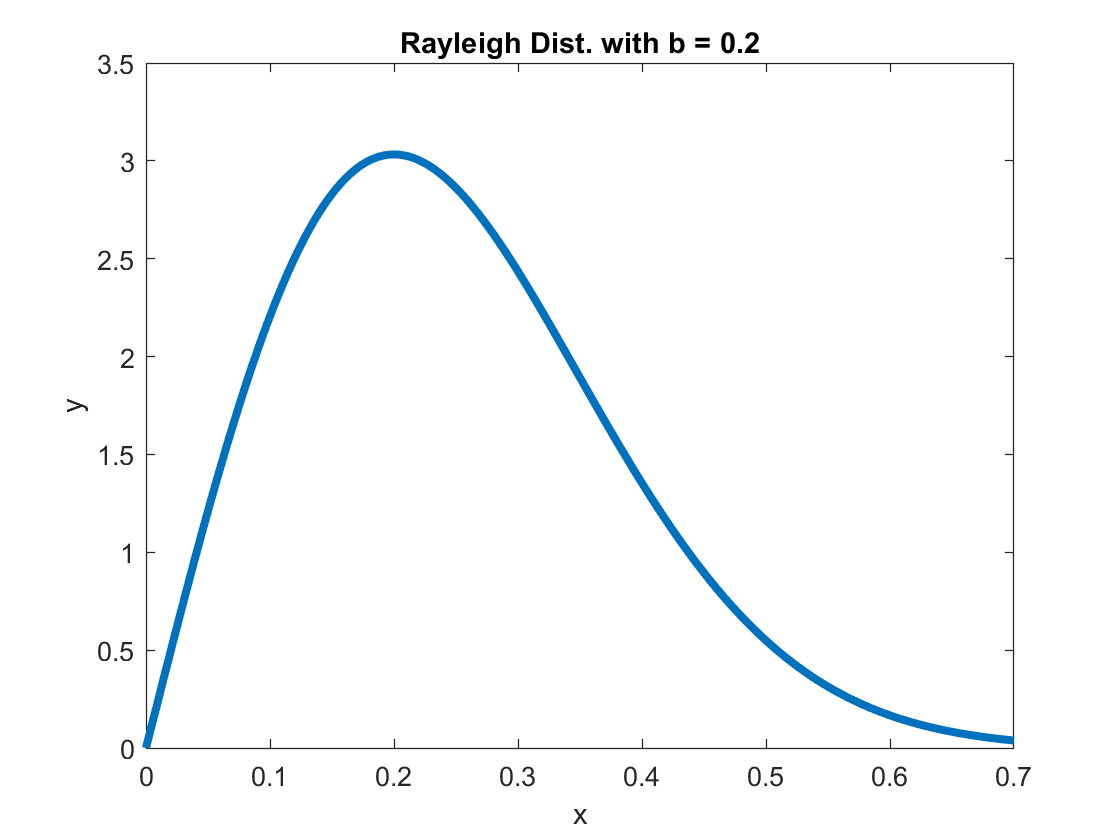

x_5 = linspace(0,0.7,1000);
rayleigh = makedist("Rayleigh",'b',0.2);
plot(x_5,pdf(rayleigh,x_5),"LineWidth",3)

title('Rayleigh Dist. with b = 0.2')
xlabel('x')
ylabel('y')

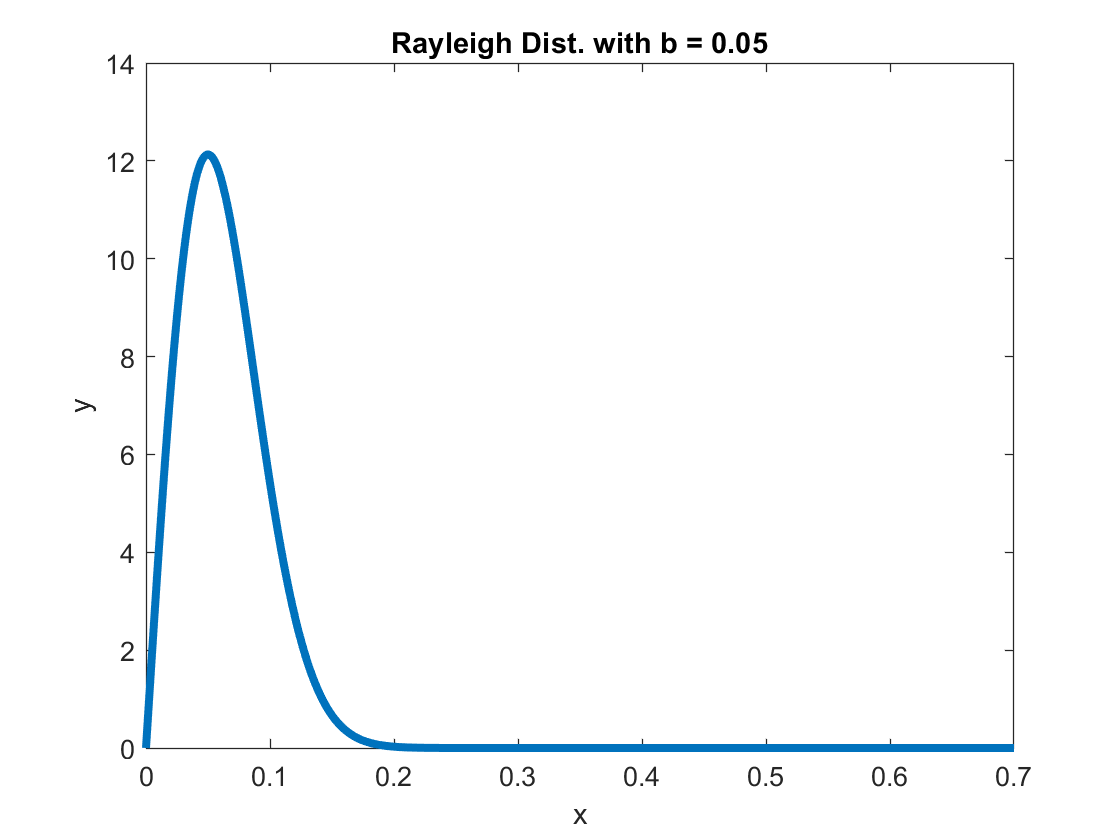


x_6 = linspace(0,0.7,1000);
rayleigh_2 = makedist("Rayleigh",'b',0.05);
plot(x_6,pdf(rayleigh_2,x_6),"LineWidth",3)

title('Rayleigh Dist. with b = 0.05')
xlabel('x')
ylabel('y')

As you can see, the larger 'b', or sigma, results in a more spread out, softer peak. 

Now for a histogram from the random set of data points d that I generated at the start of section (2):

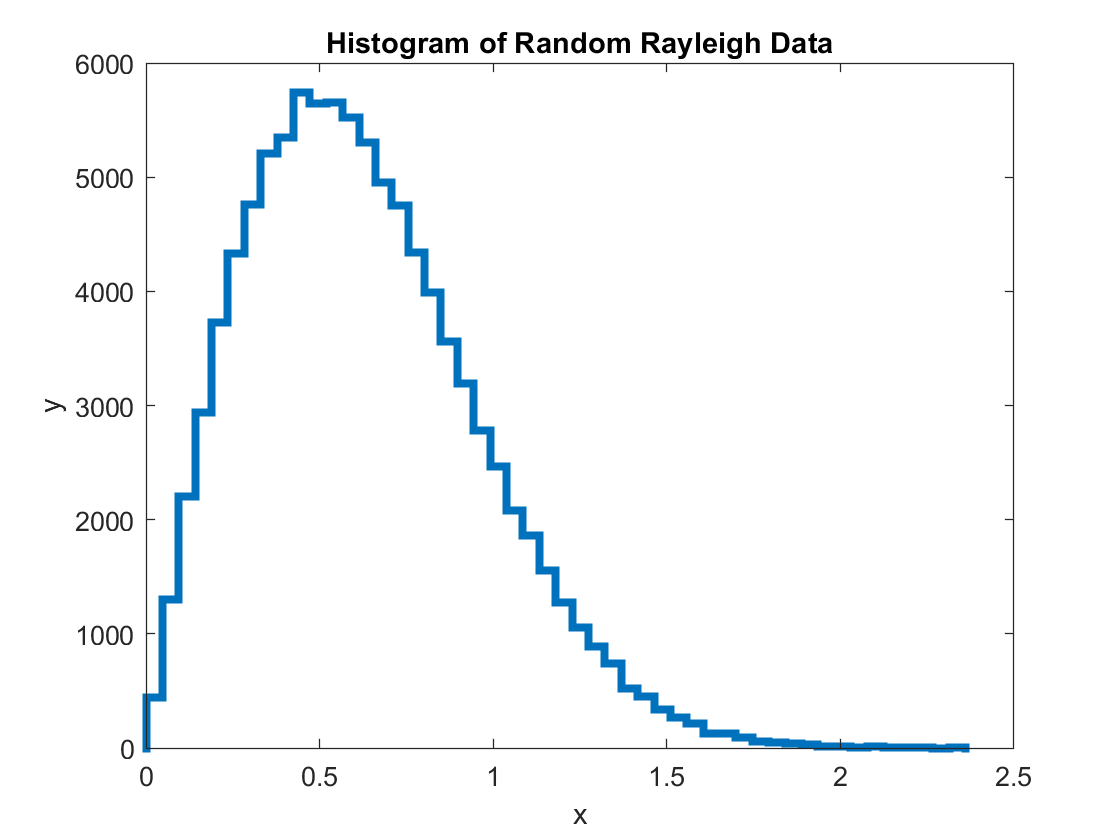

histogram(d,50,'DisplayStyle',"stairs",'Linewidth',3)
xlim([0,2.5])

title('Histogram of Random Rayleigh Data')
xlabel('x')
ylabel('y')

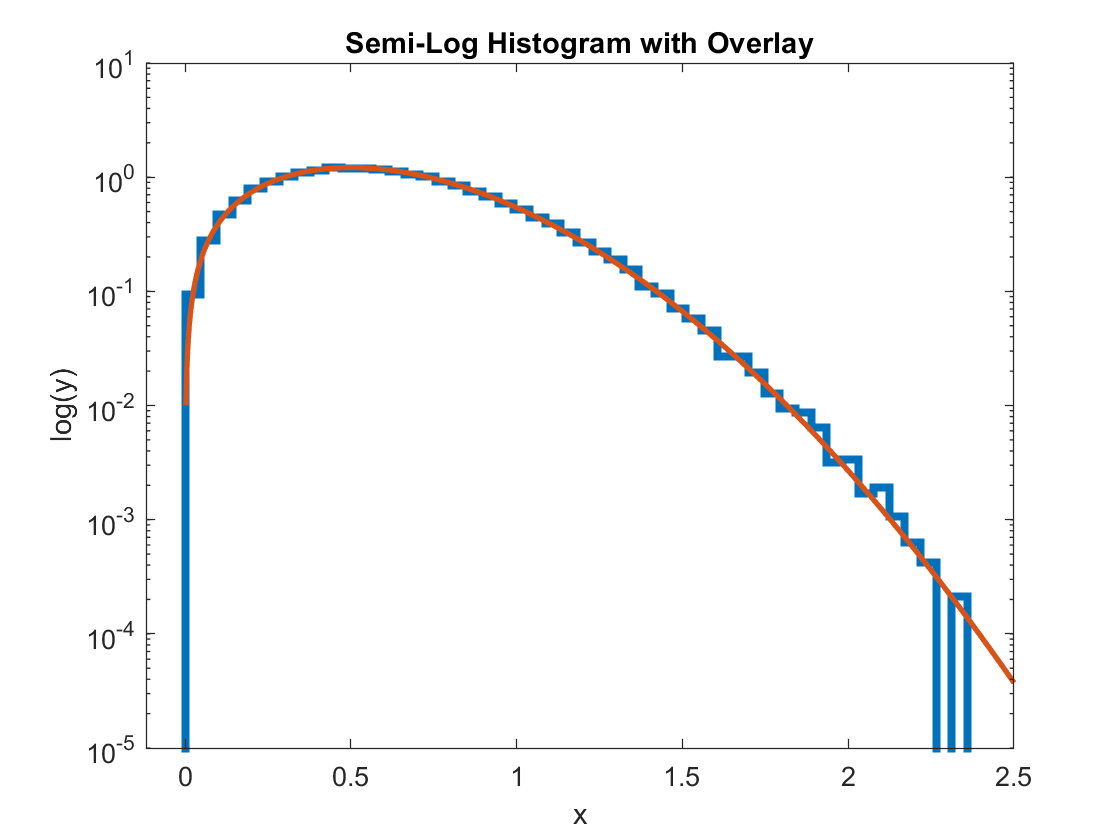


histogram(d,50,'DisplayStyle',"stairs",'Linewidth',3,"Normalization","pdf")
hold on
x_7 = linspace(0,2.5,1000);
pd = makedist("Rayleigh","b",0.5);
plot(x_7,pdf(pd,x_7),"Linewidth",2);
set(gca, 'YScale','log')

xlim([-0.12 2.50])
ylim([0.00 10.00])
title('Semi-Log Histogram with Overlay')
xlabel('x')
ylabel('log(y)')

## 3. Determining 'Sigma' for Some Chosen Value in My Distribution

### A. What's my value?

ooh decisions I don't know... 

### B. 'The Question,' in Words

state the question in words here

### C. Conversion of 'The Question' into an Integral

convert the question into a mathematical integral expression :)

### D. Calculating the Probability

### E. What's the Sigma?

- Select a value for your hypothetical measurement

- Clearly state the statistical question you want to ask in words

- Convert your word question into a mathematical integral

- Use the math to calculate the probability that the background produced the signal (Hint: you will want to use the statistics functions to do the integrals. `cdf()` and `icdf()` in MatLab; `.cdf()` and `.ppf()` in scipy).

## 4. A Bit of Experimentation

Try various hypothetical measurement values and see how the probabilities and 'sigmas' change. Discuss the patterns that you see.

# Non-Continuous Distributions

## 1. The Binomial Distribution

One of you will study the Binomial, and the other the Poisson. Flip a coin to figure out who does which.

- Read up on the distributions

- Make a series of plots with different parameters; and explain the features. (Hint: your plots will need to be discrete, sometimes 'stairs' style plots can be helpful).

- Again define a hypothetical question (clearly stated), and calculate the corresponding probability

- Because the distributions are discrete, so are the probabilities and 'sigmas'. Think about this and discuss the implications for experiments.

- While the results are discrete, the parameters of the distributions are not. For example, the mean of a Poisson distribution can be 9.2. Think about and explain why this makes sense and what changes continuously and what doesn't.